**Import Data**

tic
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
% read data from excel S&P500.csv
StockData = readtable('AAPL.csv','ReadVariableNames',true);

**Pre-Proccessing**

Data types are checked

%Ensures the data is the correct data type
if isnumeric(StockData.Open) == false
    Open =cellfun(@str2double,StockData.Open);
    High = cellfun(@str2double,StockData.High);
    Low = cellfun(@str2double,StockData.Low);
    Close = cellfun(@str2double,StockData.Close);
    AdjustedClose = cellfun(@str2double,StockData.AdjClose);
    Volume = cellfun(@str2double,StockData.Volume);
else
    Open = StockData.Open;
    High = StockData.High;
    Low = StockData.Low;
    Close = StockData.Close;
    AdjustedClose = StockData.AdjClose;
    Volume =  StockData.Volume;
end
Date = StockData.Date;

%Changes the data from table to timetable
StockData_TimeTable = timetable(Date,Open,High,Low,Close,Volume);

Checks for missing data

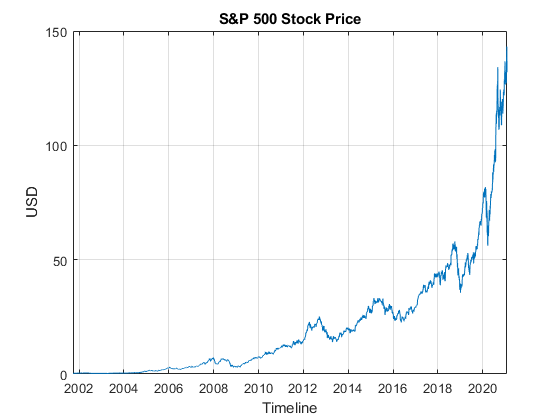

%Checks for missing Data
%Fills the missing data with previous value -- needs replaced to conform
%with plan
if any(any(ismissing(StockData_TimeTable)))==true
    StockData_TimeTable = fillmissing(StockData_TimeTable,'previous');
end

%View the data
plot(StockData_TimeTable.Date,StockData_TimeTable.Close);
title('S&P 500 Stock Price');
ylabel('USD');
xlabel('Timeline');
grid on

% get Year 2016 data out
tr = timerange('2020-01-01' , '2020-12-31');
StockData_TimeTable_2016 = StockData_TimeTable(StockData_TimeTable.Date(tr),:);
% clear unwanted variables
clear ('Open','Close','Date','AdjustedClose','High','Low','Volume','tr','StockData');

## Exploratory Data Analysis

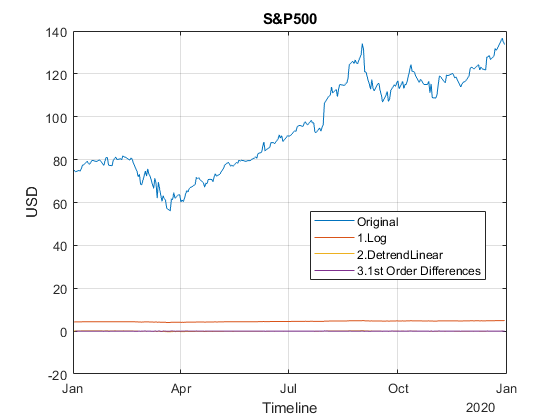

% Transform Data into Stationary Data

% Log
StockData_TimeTable_2016.CloseLog = log(StockData_TimeTable_2016.Close);

% Remove Linear trend
StockData_TimeTable_2016.CloseLogLinear = detrend(StockData_TimeTable_2016.CloseLog);

%Perform Differences
CloseLogLinearDifferences = diff(StockData_TimeTable_2016.CloseLogLinear);

%View the data
figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.CloseLog);
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.CloseLogLinear);
plot(StockData_TimeTable_2016.Date(2:end),CloseLogLinearDifferences);
title('S&P500');
ylabel('USD');
xlabel('Timeline');
legend('Original','1.Log','2.DetrendLinear','3.1st Order Differences','Location','best')
grid on
hold off

% Test Stationary
% Hypothesis test : Augmented Dickey-filer, KPSS, Leybourne-McCabe, Philip-Peron, Variance Ratio
% Hypothesis test : Egale's ARCH, Ljung-Box Q-test
[h,~] = adftest(CloseLogLinearDifferences);
% if test is valid, it will return 1 or else 0
% P-Value will also verify the stationarity of data, It may get extremely low if your data is not valid.
display(h)

h = logical
   1


CloseDiff = diff(StockData_TimeTable_2016.Close);
[h,p] = adftest(CloseDiff);
display(h)

h = logical
   1


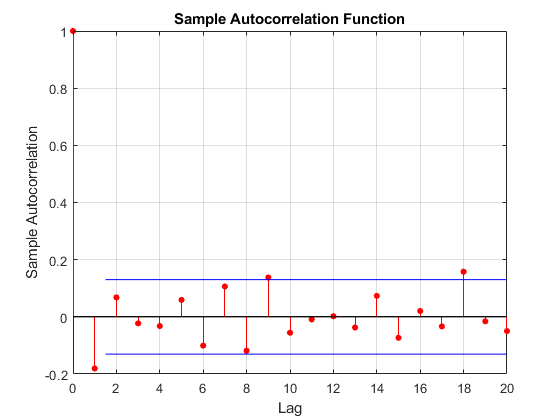

% Autocorrelaton function (ACF)
% Identify series with serial correlation
% Determines whether an AR model is apprpriate
% Identifies significant MA lags for model identification
figure
autocorr(CloseDiff,'NumLags',20,'NumMA',1)

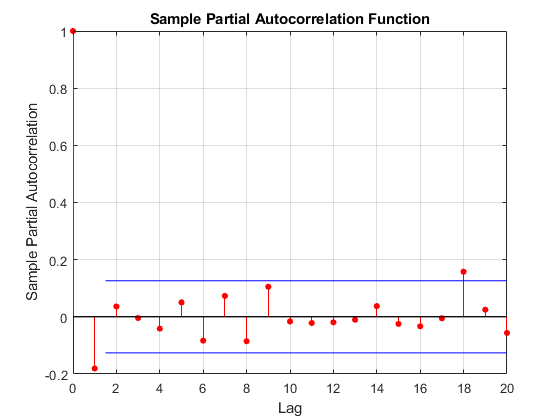

% Partial ACF (PACF)
% Identify Series with Serial Correlation
% Determines whether an MA model is appropriate
% Identifies significant AR lags for model identification.
parcorr(CloseDiff,'NumAR',1,'NumLags',20);

## ARIMA Modelling

ARIMA_Close = arima(0,1,0);
[ARIMA_Close1,~,Loglikehood] = estimate(ARIMA_Close,StockData_TimeTable_2016.Close);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.22992       0.16495         1.3939         0.16334
    Variance      6.752       0.40678         16.598      7.1465e-62



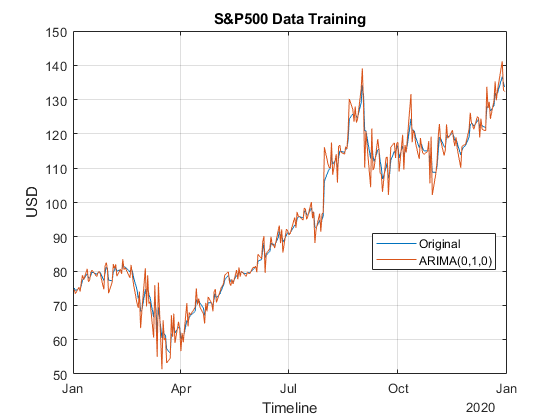

rng(1); % For reproducibility

%View the predictive vallue
residual = infer(ARIMA_Close1,StockData_TimeTable_2016.Close);
prediction = StockData_TimeTable_2016.Close + residual;

figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,prediction);
title('S&P500 Data Training');
ylabel('USD');
xlabel('Timeline');
legend('Original','ARIMA(0,1,0)','Location','best');
grid on
hold off

[aic,bic] = aicbic(Loglikehood,2,250);

## **Find the best fit model of ARIMA**

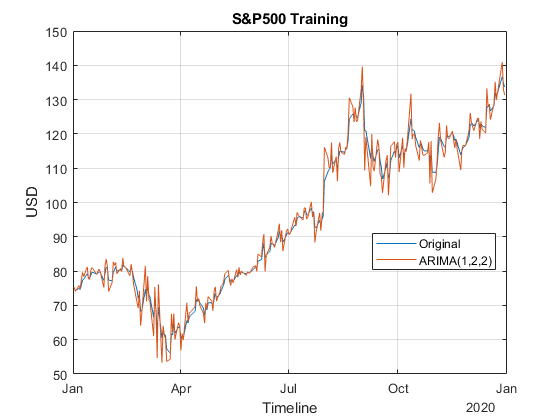

Name = "Arima(1,2,2)";
AIC = aic;
BIC = bic;

W=2;
for i = 1:2
    for j = 1:2
        for k=1:2
            ARIMA_CloseE(W-1) = arima(i,j,k);
            [~,~,LoglikehoodE] = estimate(ARIMA_CloseE(W-1),StockData_TimeTable_2016.Close,'display','off');
            [aicE,bicE] = aicbic(LoglikehoodE,2,250);
            a=convertCharsToStrings(strcat('Arima(',num2str(i),',',num2str(j),',',num2str(k),')'));
            Name(W) = a;
            AIC(W) = aicE;
            BIC(W) = bicE;
            W=W+1;
        end
    end
end

TableComparison = table;
TableComparison = table(Name',AIC',BIC');


ARIMA_CloseFinal = arima(1,2,2);
[ARIMA_CloseFinal,~,LoglikehoodE] = estimate(ARIMA_CloseFinal,StockData_TimeTable_2016.Close,'display','off');

rng(1);

residual = infer(ARIMA_CloseFinal,StockData_TimeTable_2016.Close);
prediction = StockData_TimeTable_2016.Close + residual;

figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,prediction);
title('S&P500 Training');
ylabel('USD');
xlabel('Timeline');
legend('Original','ARIMA(1,2,2)','Location','best');
grid on
hold off

## FORECASTING THE DATA

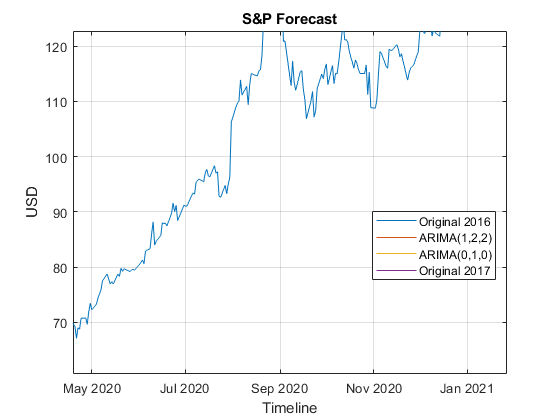

% sets the time range for the predication
tr = timerange('2021-01-01','2021-01-30');
StockData_TimeTable_2017=StockData_TimeTable(StockData_TimeTable.Date(tr),:);
len=length(StockData_TimeTable_2017.Close);
ARIMA_CloseFinalForecast1 = forecast(ARIMA_Close1,len,'Y0',StockData_TimeTable_2016.Close);
ARIMA_CloseFinalForecast2 = forecast(ARIMA_CloseFinal,len,'Y0',StockData_TimeTable_2016.Close);
%plots the forecast
figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
%first forecast
plot(StockData_TimeTable_2017.Date,ARIMA_CloseFinalForecast1);
%secon forecast
plot(StockData_TimeTable_2017.Date,ARIMA_CloseFinalForecast2);
plot(StockData_TimeTable_2017.Date,StockData_TimeTable_2017.Close);
title('S&P Forecast');
ylabel('USD');
xlabel('Timeline');
legend('Original 2016','ARIMA(1,2,2)','ARIMA(0,1,0)','Original 2017','Location','best');
grid on
hold off

observed = StockData_TimeTable_2017.Close;
prediction = ARIMA_CloseFinalForecast2;
mape = mean(abs((observed - prediction)./observed))*100

mape = 5.6952

toc

Elapsed time is 28.848929 seconds.
